# sEMG Signal Pre-processing

## basic experiment parameters

Fs = 2000; %Sampling Freq 2 KHz
Ts = 1 / Fs; %Sampling Time
[num_samples, NoC] = size(emg); %No. of Channels corr. to No. of muscles

time = (0:1:(num_samples-1)) * Ts;

## plotting raw sEMG signals

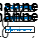

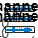

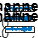

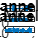

for i=0:3

    figure
    index = ((i*3)+1);
    for j= index:index+2

        subplot(3,1,(j-(3*i)))
        plot(time,emg(:,j));
        xlabel('Time (s)');
        ylabel('Voltage');
        title(strcat('Channel: ', num2str(j)));
    
        grid
        hold on
    end
    sgtitle('Raw sEMG Signals')
    hold off;
end

## Frequency Analysis

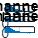

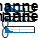

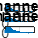

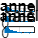

f = (Fs/num_samples) * (0:(num_samples/2));
n = 2 ^ nextpow2(num_samples);

for i=0:3

    figure
    index = ((i*3)+1);
    for j=index:index+2
        %two-sided Spectrum
        F_2 = abs((fft(emg(:,j),n)/num_samples));
        %one-sided Spectrum
        F_1 = F_2(1:( floor(num_samples/2) + 1 ));
        F_1(2:(end-1)) = 2 * F_1(2:(end-1)); %rescaling energy

        %plotting results
        subplot(3,1,(j-(3*i)))
        plot(f,F_1);
        xlabel('Frequency (Hz)');
        ylabel('Intensity');
        title(strcat('Channel: ', num2str(j)));
    
        grid
        hold on

    end
    sgtitle('sEMG Signals Spectrum')
    hold off;
end

## Band-pass filtering

Fn = Fs/2; %Nyquist Freq
LP = 25; %low cut-off
HP = 350; %high cut-off

[b, a] = butter(4,[LP,HP]/Fn,'bandpass');

emg_filt = zeros(num_samples, NoC); %band-pass filtered data

for i=1:NoC
    emg_filt(:,i) = filtfilt(b,a,emg(:,i));
end

## Full-wave Rectification

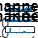

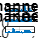

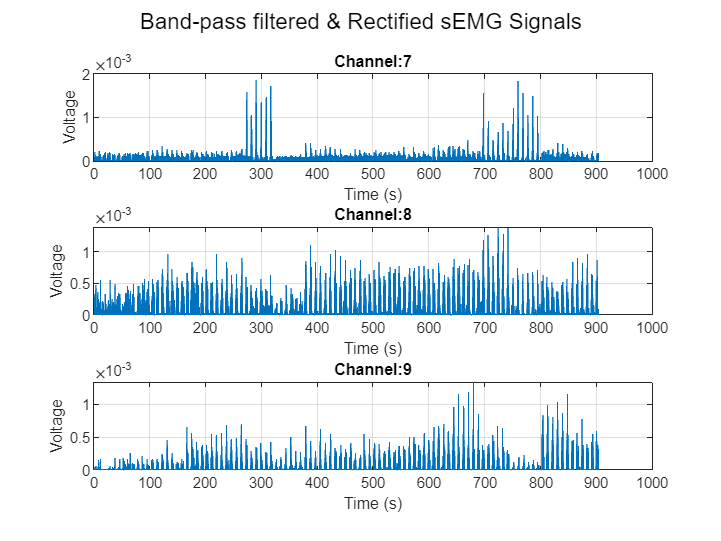

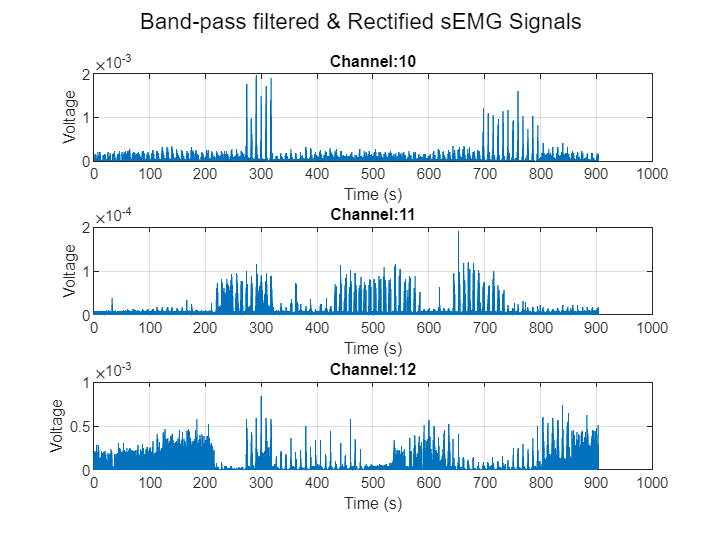

emg_rect = abs(emg_filt);

%plotting band-pass filtered and rectified sEMG signals
for i=0:3

    figure
    index = ((i*3)+1);
    for j= index:index+2

        subplot(3,1,(j-(3*i)))
        plot(time,emg_rect(:,j));
        xlabel('Time (s)');
        ylabel('Voltage');
        title(strcat('Channel: ', num2str(j)));
    
        grid
        hold on
    end
    sgtitle('Band-pass filtered & Rectified sEMG Signals')
    hold off;
end

## RMS Envelope Generation

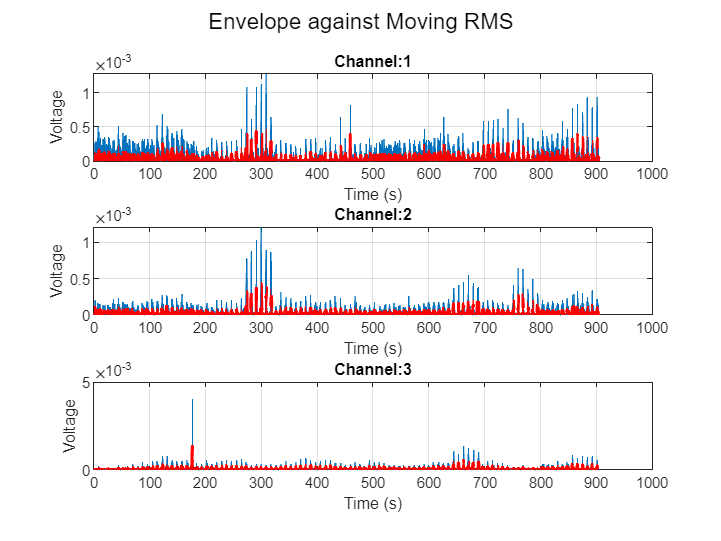

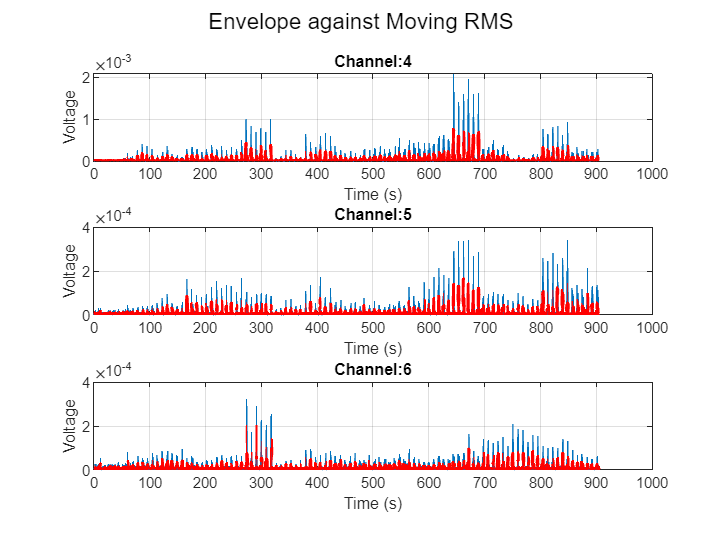

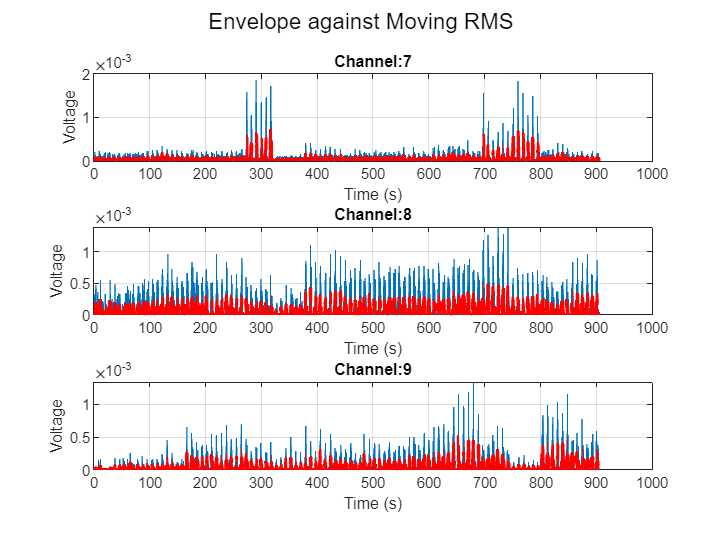

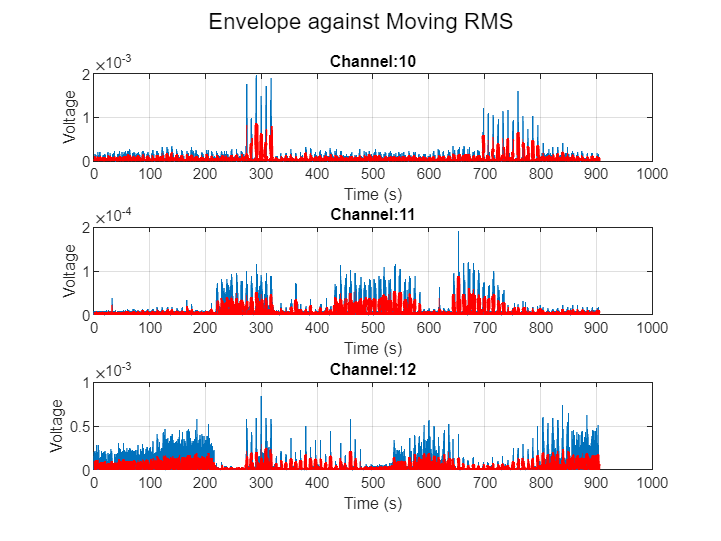

emg_envelope = zeros(num_samples,NoC);

window = 50;

for i=1:NoC
    emg_envelope(:,i) = sqrt(movmean(emg_rect(:,i).^2,window));
end

%plotting envelope against Moving RMS
for i=0:3

    figure
    index = ((i*3)+1);
    for j= index:index+2

        subplot(3,1,(j-(3*i)))
        plot(time,emg_rect(:,j));
        hold on

        plot(time,emg_envelope(:,j),'r','linewidth',2)

        xlabel('Time (s)');
        ylabel('Voltage');
        title(strcat('Channel: ', num2str(j)));
    
        grid
        hold on
    end
    sgtitle('Envelope against Moving RMS')
    hold off;
end

## MVC Normalization

MVCs = max(abs(emg));

MVC_normalized = zeros(num_samples, NoC);

for i=1:NoC
    MVC_normalized(:,i) = (emg_envelope(:,i) ./ MVCs(1,i)).*100;
end